hum_percent = [20 30 40 50];
hum = (hum_percent - 35) ./ 5;
elec_cond = [8 23 28 34];
scatter(hum, elec_cond)
hold on

% LINEAR FIT
lin_coeffs = best_fit(hum, elec_cond, 1)

     1    -3
     1    -1
     1     1
     1     3



lin_coeffs =    23.2500    4.1500


graph_poly(lin_coeffs, 4)

% QUADRATIC FIT
quad_coeffs = best_fit(hum, elec_cond, 2)

     1    -3     9
     1    -1     1
     1     1     1
     1     3     9



quad_coeffs =    26.0625    4.1500   -0.5625


graph_poly(quad_coeffs, 4)

% CUBIC FIT
cub_coeffs = best_fit(hum, elec_cond, 3)

     1    -3     9   -27
     1    -1     1    -1
     1     1     1     1
     1     3     9    27



cub_coeffs =    26.0625    2.2708   -0.5625    0.2292


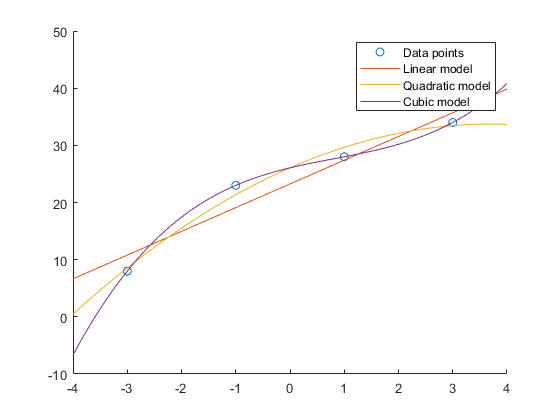

graph_poly(cub_coeffs, 4)

legend('Data points', 'Linear model', 'Quadratic model', 'Cubic model')


% Use linear model for both interpolation and extrapolation
% Data points taken are random and there are always sources of error.
% Linear model lies within cubic and quadratic on right side, and all
% models are kind of similar when interpolating.


function [coeffs] = best_fit(x, y, deg)
    A = ones(length(x), deg+1);
    for i = 1:deg
        A(:,i+1) = (x.^i)';
    end
    disp(A)
    b = y';
    A_star = A'*A;
    b_star = A'*b;
    coeffs = (inv(A_star)*b_star)';
end


function [] = graph_poly(coeffs, xsize)
    x = -xsize : 0.1 : xsize;
    exponents = 0 : 1 : length(coeffs)-1;
    y = ones(1, length(x));
    y_ind = 1;
    for i = x
        x_to_sub = ones(1, length(coeffs)).*i;
        exped_x = x_to_sub.^exponents;
        y(y_ind) = sum(exped_x.*coeffs);
        y_ind = y_ind + 1;
    end
    plot(x,y,'-')
end
